Re = 10000000;
Mach = 0.6;
MachSlow = 0.16;

[wing.data, wing.foil] = xfoil('NACA 2412',-2:0.5:11,Re,Mach,'oper iter 60','ppar N 181','oper xtr 0.1 0.1');

C:\Users\joran\Documents\GitHub\mod10project\xfoil


[wing10.data, wing10.foil] = xfoil('NACA 2412',-2:0.5:19,Re,MachSlow,'gdes flap 0.7 0 10','oper iter 60','ppar N 181','oper xtr 0.1 0.1');

C:\Users\joran\Documents\GitHub\mod10project\xfoil


[wing20.data, wing20.foil] = xfoil('NACA 2412',-2:0.5:19,Re,MachSlow,'gdes flap 0.7 0 20','oper iter 60','ppar N 181','oper xtr 0.1 0.1');

C:\Users\joran\Documents\GitHub\mod10project\xfoil


[tail.data, tail.foil] = xfoil('NACA 0012',-2:0.5:8,Re,Mach,'oper iter 60','ppar N 181','oper xtr 0.1 0.1');

C:\Users\joran\Documents\GitHub\mod10project\xfoil


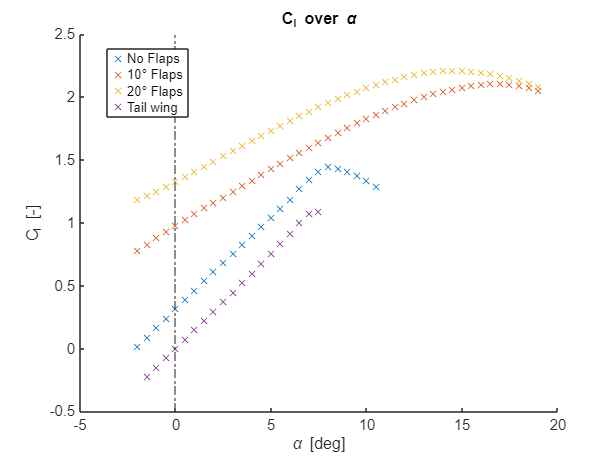

figure
hold on
xline(0,'-.','HandleVisibility','off')
plot(wing.data.alpha, wing.data.CL, 'x')
plot(wing10.data.alpha, wing10.data.CL, 'x')
plot(wing20.data.alpha, wing20.data.CL, 'x')
plot(tail.data.alpha, tail.data.CL, 'x')
legend(["No Flaps", "10° Flaps", "20° Flaps", "Tail wing"], "Position", [0.1757 0.7479 0.1295, 0.1464])

title('C_l over \alpha')
ylabel('C_l [-]')
xlabel('\alpha [deg]')


disp(['Wing: ', num2str(max(wing.data.CL))])

Wing: 1.4459


disp(['Wing 10: ', num2str(max(wing10.data.CL))])

Wing 10: 2.1056


disp(['Wing 20: ', num2str(max(wing20.data.CL))])

Wing 20: 2.2136


disp(['Tail: ', num2str(max(tail.data.CL))])

Tail: 1.0913
